% Template for MXB201 Project Part II.

## Initialisation

clear
d = dir('faces/*.pgm');
N = length(d);
I = imread([d(1).folder, '/', d(1).name]);
[rows,cols] = size(I);
M = rows*cols;
A = zeros(M, N)  % big matrix, whose columns are the images

A =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   

## Read images as columns of the matrix

for j = 1:N
    I = imread([d(j).folder, '/', d(j).name]);
    A(:,j) = I(:);
end

## Calculate and visualise mean face

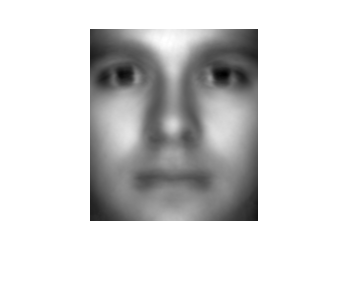

I =   Image with properties:

           CData: [192×168 double]
    CDataMapping: 'scaled'

  Show all properties


MeanA = mean(A, 2);
ReA = reshape(MeanA, [rows, cols]);
I = imshow(ReA, [])

## Calculate mean-centred SVD

MCA = A - MeanA;
[U,Sigma,V] = svd(MCA, 'econ');
sigma = diag(Sigma)

sigma = 1.0e+05 *

    1.4981
    1.3162
    0.8023
    0.5178
    0.4554
    0.4080
    0.3869
    0.3534
    0.2989
    0.2900


## Visualise first 20 eigenfaces

NewU = U(:,1:20);
width = width(NewU)

width = 20

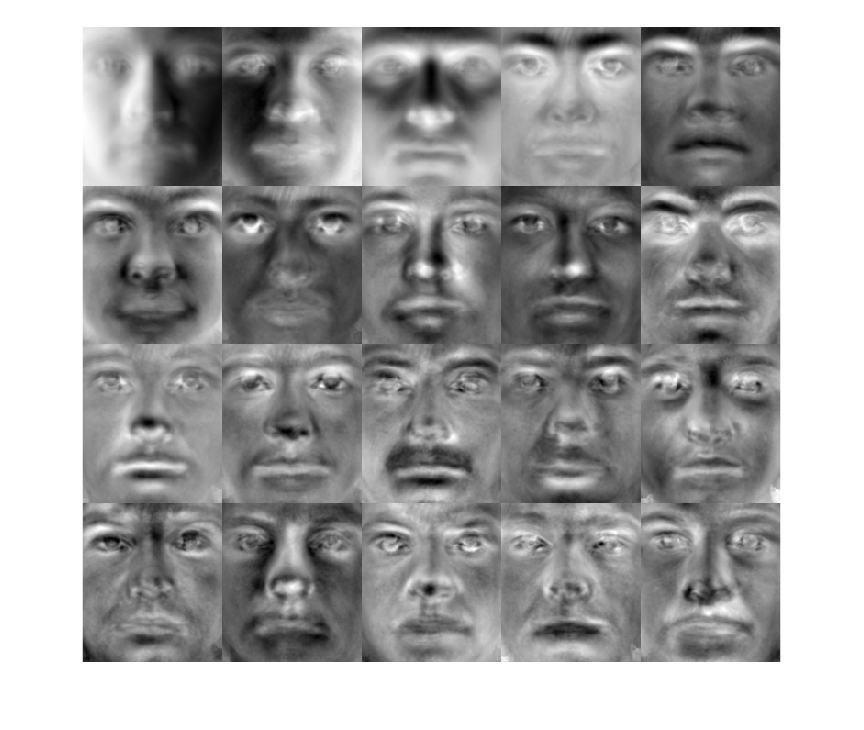

EF = zeros(rows*cols, 1);
ShapedEF = zeros(rows, cols, width);
ShapedEFScaled = zeros(rows, cols, width);

for j = 1:width
    EF = NewU(:, j);
    ShapedEF(:, :, j) = reshape(EF, [rows, cols]);
    ShapedEFScaled(:, :, j) = rescale(ShapedEF(:, :, j), 0, 1);
end

montage(ShapedEFScaled)

## Calculate coordinate vectors

% cut when sigma < 10^4
cut = 46

cut = 46

reducedU = U(:,1:cut)

reducedU =     0.0047   -0.0063   -0.0008   -0.0030   -0.0074    0.0077    0.0020   -0.0010   -0.0099    0.0024   -0.0019    0.0029   -0.0035   -0.0023   -0.0002   -0.0048   -0.0044   -0.0044    0.0006    0.0049   -0.0004   -0.0082    0.0075   -0.0013   -0.0003    0.0060    0.0014    0.0019    0.0111   -0.0007   -0.0008   -0.0043    0.0087    0.0000   -0.0061    0.0079    0.0051    0.0015   -0.0017    0.0079    0.0058   -0.0012    0.0107    0.0082    0.0010   -0.0022
    0.0048   -0.0064   -0.0008   -0.0029   -0.0075    0.0078    0.0016   -0.0006   -0.0097    0.0023   -0.0011    0.0025   -0.0042   -0.0031   -0.0004   -0.0043   -0.0045   -0.0043    0.0002    0.0056   -0.0006   -0.0078    0.0066   -0.0016    0.0003    0.0049    0.0016    0.0009    0.0117   -0.0015   -0.0006   -0.0033    0.0079   -0.0007   -0.0053    0.0081    0.0041    0.0011   -0.0014    0.0081    0.0044   -0.0012    0.0104    0.0074    0.0008   -0.0007
    0.0048   -0.0063   -0.0009   -0.0031   -0.0077    0.0076    0.0

reducedSigma = Sigma(1:cut,1:cut)

reducedSigma = 1.0e+05 *

    1.4981         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    1.3162         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8023         0         0  

reducedVT = V(:,1:cut)'

reducedVT =    -0.0087   -0.0115   -0.0100   -0.0017    0.0103   -0.0061    0.0016    0.0028    0.0120    0.0067    0.0187    0.0210    0.0363    0.0307    0.0419    0.0410    0.0472   -0.0104   -0.0217   -0.0248   -0.0135   -0.0376   -0.0465   -0.0262   -0.0066   -0.0420   -0.0589   -0.0503   -0.0422   -0.0129   -0.0120   -0.0037   -0.0096    0.0011   -0.0106   -0.0077   -0.0051    0.0018    0.0039    0.0125    0.0299    0.0255    0.0033    0.0321    0.0361    0.0347   -0.0108   -0.0278   -0.0288   -0.0202
   -0.0214   -0.0273   -0.0178   -0.0080    0.0194   -0.0352   -0.0257   -0.0447   -0.0156   -0.0350   -0.0285   -0.0163    0.0301    0.0037   -0.0358   -0.0228   -0.0007   -0.0082   -0.0289   -0.0184    0.0039   -0.0304   -0.0239   -0.0048    0.0382   -0.0034    0.0116    0.0166    0.0285   -0.0235   -0.0275   -0.0122   -0.0093    0.0182   -0.0364   -0.0291   -0.0458   -0.0195   -0.0333   -0.0302    0.0516    0.0262   -0.0636   -0.0388   -0.0242   -0.0042   -0.0053   -0.0303   -0.0

% Coordinate vector matrix C (columns are coordinate vectors)
C = reducedSigma*reducedVT

C = 1.0e+04 *

   -0.1304   -0.1730   -0.1491   -0.0259    0.1544   -0.0914    0.0242    0.0423    0.1797    0.1011    0.2797    0.3149    0.5443    0.4602    0.6278    0.6149    0.7070   -0.1554   -0.3255   -0.3715   -0.2024   -0.5630   -0.6972   -0.3931   -0.0983   -0.6291   -0.8828   -0.7530   -0.6326   -0.1931   -0.1799   -0.0549   -0.1434    0.0172   -0.1590   -0.1158   -0.0770    0.0269    0.0586    0.1867    0.4479    0.3818    0.0498    0.4813    0.5415    0.5194   -0.1618   -0.4171   -0.4315   -0.3023
   -0.2811   -0.3591   -0.2345   -0.1047    0.2555   -0.4631   -0.3378   -0.5884   -0.2054   -0.4604   -0.3750   -0.2151    0.3958    0.0492   -0.4711   -0.2997   -0.0092   -0.1079   -0.3806   -0.2418    0.0516   -0.4006   -0.3144   -0.0634    0.5022   -0.0453    0.1532    0.2180    0.3745   -0.3093   -0.3625   -0.1607   -0.1226    0.2390   -0.4797   -0.3832   -0.6034   -0.2562   -0.4381   -0.3981    0.6787    0.3442   -0.8371   -0.5111   -0.3184   -0.0556   -0.0695   -0.3991   -

## **Visualise Reduced Faces**

reducedMCA = reducedU*C

reducedMCA =    24.2904   35.9207   33.9154   17.2964    2.7675   46.5379   40.0978   59.6090   33.4211   54.5160   55.6688   41.8827   17.1913   35.0430   90.5904   79.4287   55.6531   18.0583   23.1800   13.3721   -2.3163   21.0961    4.5703   -3.0646  -31.8676  -12.4054  -28.8101  -33.7675  -43.8390   22.1304   33.5722   33.3122    9.8370  -11.5384   43.4765   32.6872   52.9025   22.3961   48.8823   49.5687  -13.6636    1.4574   75.4452   82.9353   73.8294   44.4778   14.8844   20.0373   14.1512   -7.1922
   22.8611   34.6151   33.1840   15.3073    0.8365   44.9812   38.3788   58.2986   32.1066   53.8691   55.0333   41.0294   16.2526   34.5936   90.7489   79.7563   55.1733   16.1828   20.8064   10.9491   -4.8102   18.6846    1.4677   -5.8092  -34.5457  -15.7266  -32.9040  -37.0876  -46.8997   21.5690   32.4686   31.6777    8.5759  -12.6483   41.9099   31.3884   51.5016   22.2832   48.1885   49.1864  -14.1370    0.6246   76.1140   81.4010   72.5667   43.3520   13.3889   18.3306   12.

MCA

MCA =    22.4240   36.4240    1.4240   11.4240   -4.5760   48.4240   36.4240   61.4240   32.4240   61.4240   65.4240   46.4240   10.4240   41.4240  110.4240   99.4240   60.4240   15.4240   16.4240    7.4240  -10.5760   12.4240   -4.5760   -9.5760  -39.5760  -23.5760  -40.5760  -45.5760  -48.5760   28.4240   38.4240   39.4240    9.4240  -15.5760   44.4240   33.4240   52.4240   32.4240   62.4240   63.4240   36.4240    8.4240   54.4240   87.4240   89.4240   51.4240   12.4240   15.4240    8.4240  -10.5760
   22.8360   28.8360    8.8360    8.8360   -6.1640   43.8360   33.8360   59.8360   31.8360   57.8360   61.8360   45.8360   10.8360   39.8360   98.8360   96.8360   59.8360   10.8360   13.8360    3.8360   -9.1640    6.8360  -10.1640  -12.1640  -38.1640  -25.1640  -43.1640  -48.1640  -49.1640   20.8360   37.8360   36.8360    6.8360  -18.1640   43.8360   32.8360   51.8360   23.8360   56.8360   57.8360  -35.1640    6.8360  110.8360   85.8360   87.8360   53.8360   11.8360   12.8360    7.8360  -

% Visualise reduced eigenfaces
NewreducedU = reducedU(:,1:20)

NewreducedU =     0.0047   -0.0063   -0.0008   -0.0030   -0.0074    0.0077    0.0020   -0.0010   -0.0099    0.0024   -0.0019    0.0029   -0.0035   -0.0023   -0.0002   -0.0048   -0.0044   -0.0044    0.0006    0.0049
    0.0048   -0.0064   -0.0008   -0.0029   -0.0075    0.0078    0.0016   -0.0006   -0.0097    0.0023   -0.0011    0.0025   -0.0042   -0.0031   -0.0004   -0.0043   -0.0045   -0.0043    0.0002    0.0056
    0.0048   -0.0063   -0.0009   -0.0031   -0.0077    0.0076    0.0015   -0.0002   -0.0091    0.0024   -0.0001    0.0027   -0.0048   -0.0030   -0.0009   -0.0033   -0.0044   -0.0041   -0.0007    0.0067
    0.0048   -0.0063   -0.0010   -0.0034   -0.0081    0.0070    0.0015   -0.0004   -0.0086    0.0025    0.0010    0.0029   -0.0059   -0.0030   -0.0012   -0.0024   -0.0039   -0.0039   -0.0015    0.0070
    0.0048   -0.0062   -0.0011   -0.0036   -0.0080    0.0062    0.0013   -0.0006   -0.0084    0.0029    0.0017    0.0028   -0.0066   -0.0027   -0.0012   -0.0017   -0.0037   -0.0037  

reducedEF = zeros(rows*cols, 1);
ShapedreducedEF = zeros(rows, cols, width);
ShapedreducedEFScaled = zeros(rows, cols, width);

for j = 1:width
    reducedEF = NewreducedU(:, j);
    ShapedreducedEF(:, :, j) = reshape(reducedEF, [rows, cols]);
    ShapedreducedEFScaled(:, :, j) = rescale(ShapedreducedEF(:, :, j), 0, 1);
end

montage(ShapedEFScaled)

montage(ShapedreducedEFScaled)

## Demonstrate rudimentary moustache detector

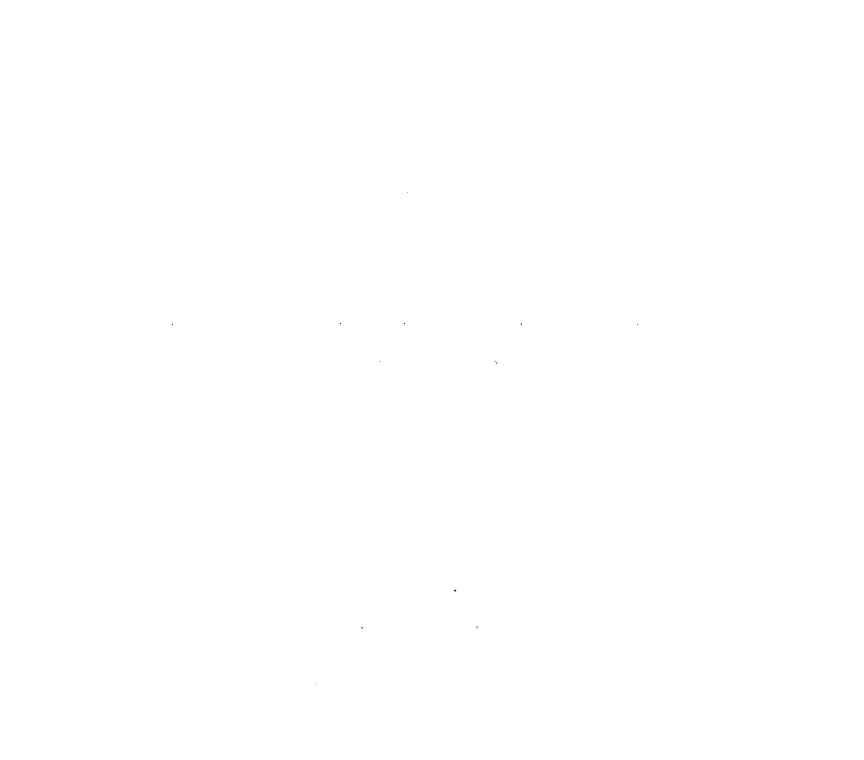

% use column 13 of U to get moustache info.
% Given eigenvector, find where it is in other image?
% Find eigenface 13 in original faces.
% original faces are linear combinations of eigenfaces.
% Find contribution of eigenface 13 in face.
% U*Sigma -> each column is column of u (eigenface) scaled by sigma of
% column in Sigma (eg U*Sigma(:,1) = Sigma(1)*U(:,1)).
% check first 30 faces for moustache.
Ims = A(:,1:30);
ShapedIms = zeros(rows, cols, 30);

for j = 1:30
    ShapedIms(:, :, j) = reshape(Ims(:,j), [rows, cols]);
end
montage(ShapedIms)

eig_13 = reducedU(:,13)
A = zeros(1,30)
for i = 1:30
    proj_MCA = dot(MCA(:,i),eig_13)/(norm(eig_13)^2)
    A(i) = proj_MCA
end